# Map Building Laser Based

**Team members:**

- Javier Cabrera

- Julia Gasull

**Link: **[https://drive.matlab.com/sharing/49eb5fa6-0641-425c-a130-9cf41b2e1058](https://drive.matlab.com/sharing/49eb5fa6-0641-425c-a130-9cf41b2e1058)

clc;
clear all;
close all

## Task to do

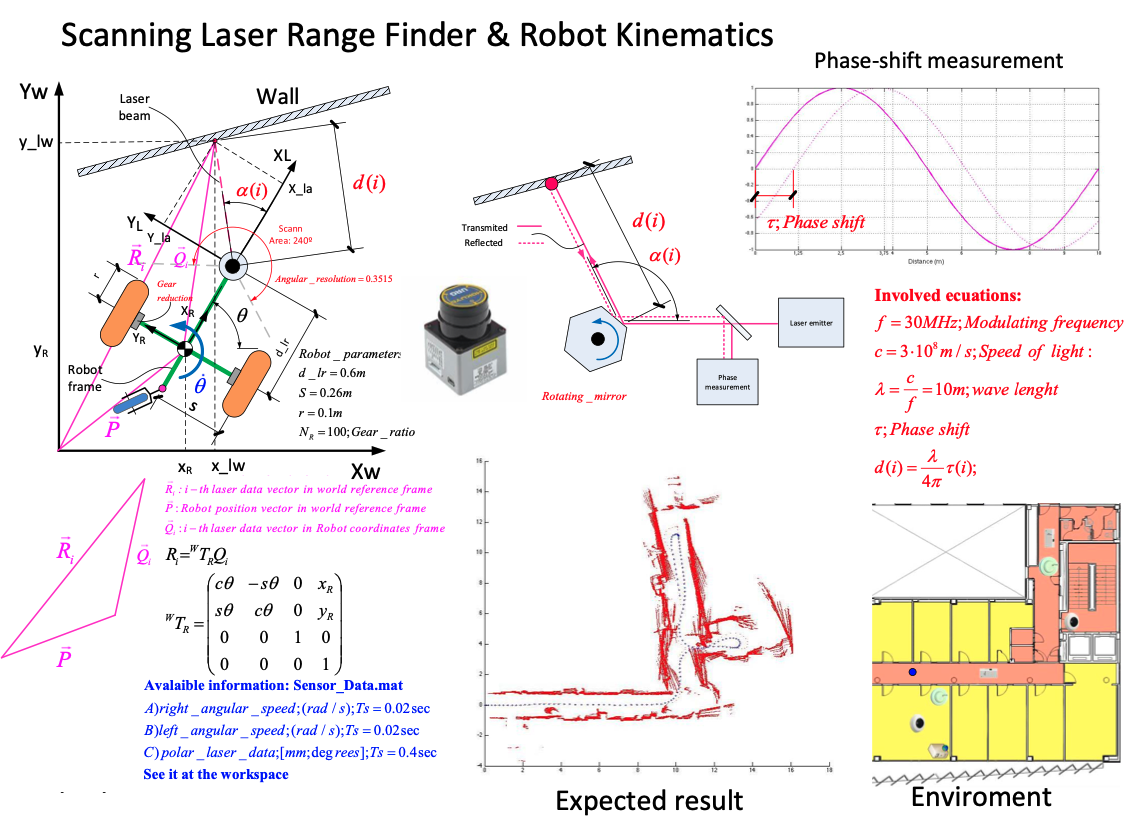

## Data

d_lr = 0.6 % m

d_lr = 0.6000

S = 0.26 % m

S = 0.2600

r = 0.1 % m

r = 0.1000

N_R = 100 % gear ratio

N_R = 100

angular_resolution = 0.3515 

angular_resolution = 0.3515

scan_area = deg2rad(240)

scan_area = 4.1888

From `Sensors_Data.mat`

load('/Users/juliagasullnavarro/Documents/uni/FIB-ROB/matlab-drive/JJ/Todos/10_Localization. Sensors/Sensors_Data.mat')
left_angular_speed

left_angular_speed =          0         0
    0.0200         0
    0.0400         0
    0.0600         0
    0.0800         0
    0.1000         0
    0.1200         0
    0.1400         0
    0.1600         0
    0.1800         0


log_urg

log_urg = 	1.0e+09 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0

polar_laser_data

polar_laser_data = 	1.0e+09 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.00

right_angular_speed

right_angular_speed =          0         0
    0.0200         0
    0.0400         0
    0.0600         0
    0.0800         0
    0.1000         0
    0.1200         0
    0.1400         0
    0.1600         0
    0.1800         0


% red dots
LandMark = [
    13.20,  9.21; 
   -01.50,  1.50;
   -01.50, -1.50;  
    05.01, -6.40
]';
figure
axis ([-2 2 -8 10])
plot( ...
    LandMark(1,:), ...
    LandMark(2,:), ...
    "Color", 'r', ...
    "LineStyle","--","LineWidth",1, ...
    "Marker",".", "MarkerSize",50 ...
)

grid on
ylabel('y'); xlabel('x'); zlabel('z');
 
% Translate an rotate the Land Marks
theta = pi/16 % Rotate pi/16 rad --> 22.5 degrees

theta = 0.1963

tx = 0.1; % Translate 
ty = 0.2;

newLM = transl2(tx,ty)*rotz(-theta)

newLM =     0.9808    0.1951    0.1000
   -0.1951    0.9808    0.2000
         0         0    1.0000


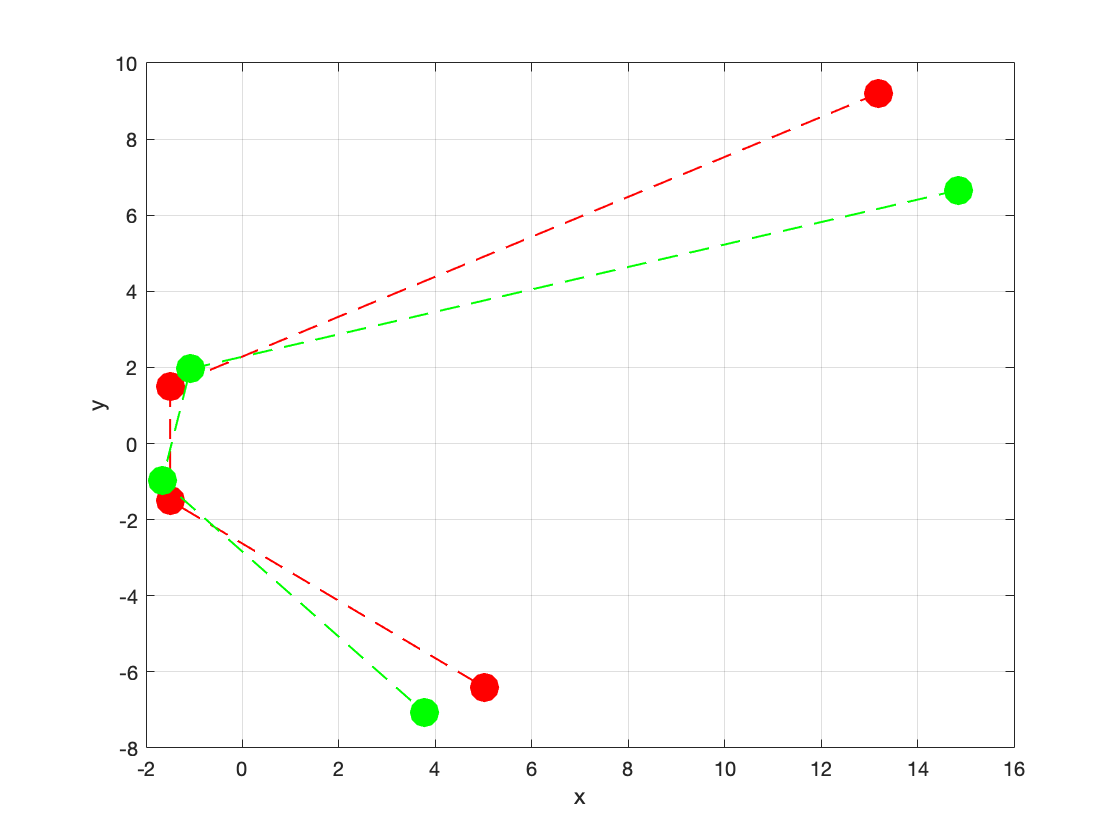

newLM = newLM*[LandMark;ones(1,4)];
 
hold on;

% green dots
plot( ...
    newLM(1,:), ...
    newLM(2,:), ...
    "Color", 'g', ...
    "LineStyle","--","LineWidth",1, ...
    "Marker",".", "MarkerSize",50 ...
)

## Similarity Transform

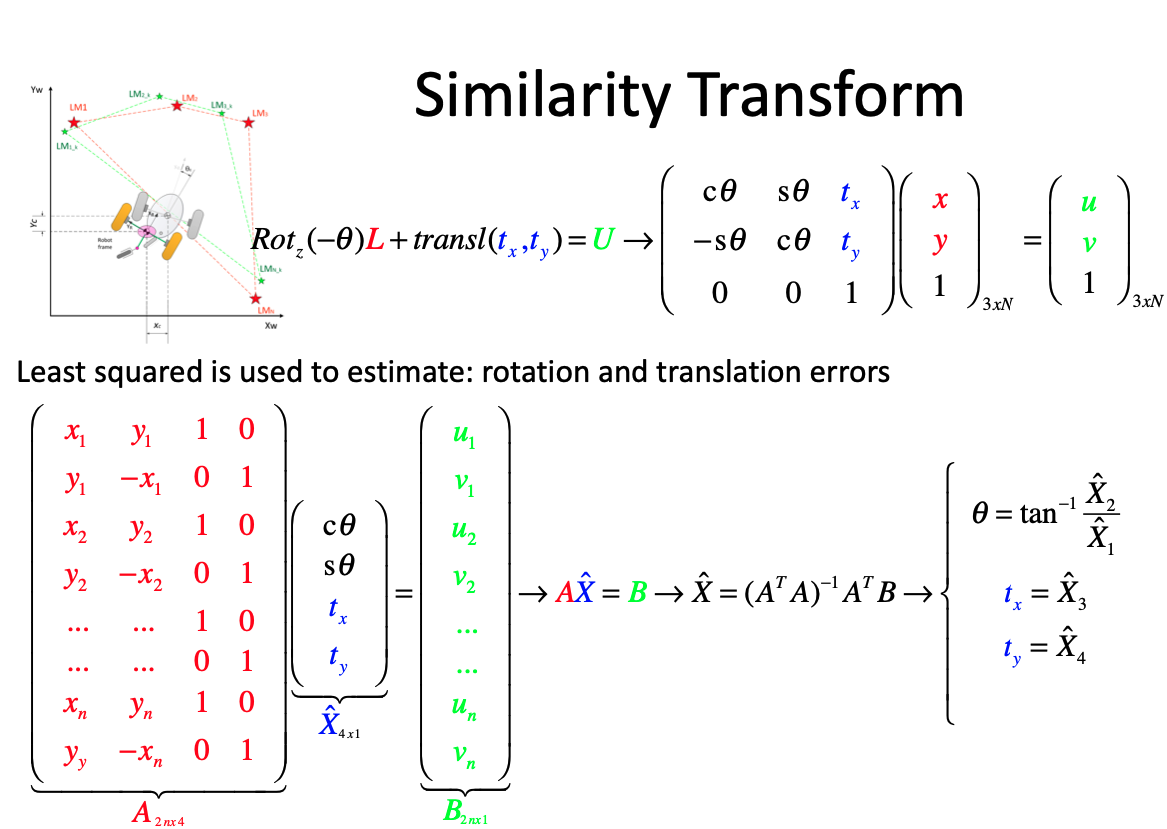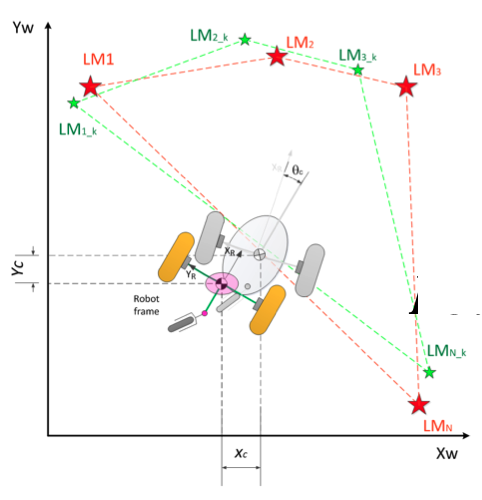

A = [];
for i=1:size(LandMark, 2)
    A = [A;[LandMark(1,i),LandMark(2,i),1,0]];
    A = [A;[LandMark(2,i),-LandMark(1,i),0,1]];
end

% Build Matrix B
B = [];
for i=1:size(newLM, 2)
    B = [B; newLM(1,i); newLM(2,i)];
end

%Compute tx ty i theta
X = inv((A'*A))*A'*B;
tx_ST = X(3)

tx_ST = 0.1000

ty_ST = X(4)

ty_ST = 0.2000

theta_ST = atan2(X(2),X(1))

theta_ST = 0.1963


%Rotamos y transladamos nuestras landmarks
matriz_correccion = trotz(theta_ST)*transl(tx_ST,ty_ST,0);
landmarks_corregidas = landmarks_nuestras*matriz_correccion; 